# **WM9QE: Applied Statistics for Artificial Intelligence**

## **Descriptive Statistics in AI Applications **

This MATLAB Live Script is a suppliment to the Descriptive Statistics session. Full detail of the lectures and examples are availabe on [Section: Week One | WM9QE:Applied Statistics for Artificial Intelligence | Moodle@Warwick](https://moodle.warwick.ac.uk/course/section.php?id=576666). 

Learning Objectives

- Understand and compute mean, median, and mode for AI datasets, and recognize when each measure is most appropriate for different data distributions

- Calculate and interpret variance, standard deviation, range, IQR, and CV, and understand when each variability measure is most appropriate

- Calculate and interpret Pearson correlation coefficient between variables

Overview

This tutorial provides hands-on experience with the descrite statistics techniques covered in the theoretical session. 

# Section 1: Central Tendency Measures

## **The Mean**

The arithmetic average of all values in a dataset. It represents the balance point of the data distribution.

Mathematical Formula


$$\bar{x}=\frac{\Sigma x_i}{n}=\frac{x_1+x_2+...+x_n}{n}$$


where $n$ is the number of observations and $x_i$ represents each individual value

Let's get familiar with the MATLAB `mean()` function:

clear all; clc;
x=[85, 92, 78, 95, 88]; %Array for testing purposes
fprintf('The mean value of x is: %.2f', mean(x)); %Display the mean() of array x.

The mean value of x is: 87.60

✓ Use When:

- Data is symmetrically distributed

- No extreme outliers present

- Continuous numerical data

✗ Limitations:

- Highly sensitive to outliers

- Can be misleading with skewed data

- May not represent typical value

## **The Median**

The middle value when data is ordered from smallest to largest. It divides the dataset into two equal halves.

Mathematical Formula

- If $n$ is odd:


$$Median = x_{(\frac{n+1}{2})}$$


- If $n$ is even:


$$Median =x_{(\frac{n}{2})} + x_{(\frac{n}{2})+1}$$


where data is sorted in ascending order

Let's get familiar with the MATLAB `median()` function:

%odd number:
n_odd=[85, 92, 78, 95, 88]; %Array for testing purposes
fprintf('The median value of n (odd) is: %.2f', median(n_odd)); %Display the median() of array n.

The median value of n (odd) is: 88.00

%event number:
n_even=[85, 92, 78, 95, 88, 76]; %Array for testing purposes
fprintf('The median value of n (even) is: %.2f', median(n_even)); %Display the median() of array n.

The median value of n (even) is: 86.50

✓ Use When:

- Data contains outliers

- Skewed distributions

- Need robust measure

⚠ Considerations:

- Requires sorting data

- Less sensitive to all data points

- Better for ordinal data

## **The Mode**

The value that appears most frequently in a dataset. A dataset can have one mode (unimodal), two modes (bimodal), multiple modes (multimodal), or no mode.

Mathematical Definition


$$\text{Mode} = \text{value with maximum frequency}$$



$$\text{Mode} = arg\max_{x} f(x)$$


where $f(x)$ is the frequency of value$ x$.

Let's get familiar with the MATLAB `mode()` function:

% Example 1: Simple vector
x=[85, 92, 78, 95, 88, 82, 78]; %Array for testing purposes
fprintf('The mode value of array x is: %d', mode(x)); %Display the mode() of array n.

The mode value of array x is: 78


% Example 2: Matrix (Mode of each column)
data_matrix = [1, 2, 3; 4, 2, 3; 1, 5, 6];
fprintf('The mode value of data_matrix is:');

The mode value of data_matrix is:

M = mode(data_matrix);
disp(M); % Output: 1  2  3 

     1     2     3



% MATLAB calculates the mode for each column by default.

✓ Use When:

- Categorical or discrete data

- Finding most common category

- Multiple peaks in distribution

✗ Limitations:

- May not exist (all unique values)

- Multiple modes possible

- Less useful for continuous data

## **Why Central Tendency Matters in AI**

1. Model Performance Evaluation

- **Mean:** Average accuracy across cross-validation folds

- **Median:** Typical performance when outlier runs exist

- **Mode:** Most frequently predicted class in classification

2. Feature Engineering

- **Mean:** Feature normalization and centering

- **Median:** Robust imputation for missing values

- **Mode:** Filling categorical missing data

3. Data Distribution Analysis

Comparing mean, median, and mode reveals distribution shape:

- `Mean ≈ Median ≈ Mode` → Symmetric distribution

- `Mean > Median` → Right-skewed (positive skew)

- `Mean < Median` → Left-skewed (negative skew)

4. Outlier Detection

Large differences between mean and median indicate potential outliers or skewness, requiring investigation before model training.

## **AI Application Example**

Analyzing training performance of a neural network across multiple runs with different random initializations.

This example aim is to train a simple neural network multiple times on a classification task (recognizing handwritten digits) and use central tendency measures to understand:

- **Mean accuracy:** Expected performance across runs

- **Median accuracy:** Typical performance (robust to outliers)

- **Mode:** Most frequent prediction patterns

- **Distribution shape:** Skewness and reliability of the model

**Dataset**: It uses the MNIST digits (subset) with 10 classes (digits 0-9).

**Method**: We will run the training phase 30 times, independently, modifying only the random seeds.

***Note: Please do not focus on the Neural Network implementation itself. The purpose is to analyse and understand the central tendency of the network's accurary. This is intended for illustration purposes for you to understand the importance of central tendency metrics in AI applications. Learning how to implement the network itself is not the purpose of this workbook.***

**Step 1: Load Data and Setup**

We will load the MNIST handwritten digits dataset and select a subset of 1000 images for faster training. The seed is set to 42 to ensure that the data selection is reproducible.

% Neural Network Training Performance Analysis
% Exercise: Central Tendency Measures

clear; clc; close all;

% Set seed for reproducibility
rng(42);

% Load MNIST digit dataset (subset)
[XTrain, YTrain] = digitTrain4DArrayData;

% Use a subset for faster training (1000 images)
numSamples = 1000;
indices = randperm(size(XTrain, 4), numSamples);
XTrain = XTrain(:,:,:,indices);
YTrain = YTrain(indices);

% Display dataset information
fprintf('Dataset Information:\n');

Dataset Information:


fprintf('Training samples: %d\n', size(XTrain, 4));

Training samples: 1000


fprintf('Image size: %dx%d\n', size(XTrain, 1), size(XTrain, 2));

Image size: 28x28


fprintf('Number of classes: %d\n', length(unique(YTrain)));

Number of classes: 10


**Step 2: Define Neural Network Architecture**

We define a simple Convolutional Neural Network (CNN) with 2 convolutional layers. This architecture is kept consistent across all training runs. Only the random initialization will vary.

% Define simple CNN architecture
layers = [
    imageInputLayer([28 28 1])
    
    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

% Training options (same for all runs except seed)
options = trainingOptions('adam', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 64, ...
    'Verbose', false, ...
    'Plots', 'none');

**Step 3: Train Network Multiple Times**

We train the same network architecture 30 times with different random initializations (`rng` seeds from 43 to 72). Each run produces an accuracy score on the validation set. We also store the predicted classes for mode analysis.

% Split data into train and validation
numTrain = floor(0.8 * numSamples);
XTrainSplit = XTrain(:,:,:,1:numTrain);
YTrainSplit = YTrain(1:numTrain);
XVal = XTrain(:,:,:,numTrain+1:end);
YVal = YTrain(numTrain+1:end);

% Multiple training runs
numRuns = 30;
accuracies = zeros(numRuns, 1);
predictedClasses = cell(numRuns, 1);

fprintf('\nTraining neural network %d times...\n', numRuns);


Training neural network 30 times...



for i = 1:numRuns
    rng(42 + i);
    
    net = trainNetwork(XTrainSplit, YTrainSplit, layers, options);
    
    YPred = classify(net, XVal);
    predictedClasses{i} = YPred;
    accuracies(i) = sum(YPred == YVal) / numel(YVal);
    
    if mod(i, 5) == 0
        fprintf('Completed %d/%d runs\n', i, numRuns);
    end
end

Completed 5/30 runs
Completed 10/30 runs
Completed 15/30 runs
Completed 20/30 runs
Completed 25/30 runs
Completed 30/30 runs



fprintf('Training complete!\n');

Training complete!


**Step 4: Calculate Mean, Median, and Mode**

We calculate the mean and median directly using MATLAB functions. For mode, we bin accuracies into ranges since continuous values rarely repeat exactly. We also find the most frequently predicted class across all runs.

% Calculate central tendency measures for accuracies
meanAccuracy = mean(accuracies);
medianAccuracy = median(accuracies);

% For mode analysis: bin accuracies into ranges
accuracyBins = 0.70:0.01:1.00;
[counts, edges] = histcounts(accuracies, accuracyBins);
[maxCount, modeIdx] = max(counts);
modeAccuracyRange = [edges(modeIdx), edges(modeIdx+1)];

% Display results
fprintf('\n=== ACCURACY STATISTICS ===\n');


=== ACCURACY STATISTICS ===


fprintf('Mean Accuracy: %.4f (%.2f%%)\n', meanAccuracy, meanAccuracy*100);

Mean Accuracy: 0.6903 (69.03%)


fprintf('Median Accuracy: %.4f (%.2f%%)\n', medianAccuracy, medianAccuracy*100);

Median Accuracy: 0.6925 (69.25%)


fprintf('Mode Accuracy Range: [%.4f, %.4f]\n', ...
    modeAccuracyRange(1), modeAccuracyRange(2));

Mode Accuracy Range: [0.7100, 0.7200]


fprintf('Min Accuracy: %.4f (%.2f%%)\n', min(accuracies), min(accuracies)*100);

Min Accuracy: 0.6350 (63.50%)


fprintf('Max Accuracy: %.4f (%.2f%%)\n', max(accuracies), max(accuracies)*100);

Max Accuracy: 0.7400 (74.00%)



% Analyze most common predictions for mode
allPredictions = [];
for i = 1:numRuns
    allPredictions = [allPredictions; predictedClasses{i}];
end
modeClass = mode(allPredictions);
fprintf('\nMost frequently predicted class: %s\n', string(modeClass));


Most frequently predicted class: 2


**Step 5: Visualize Results**

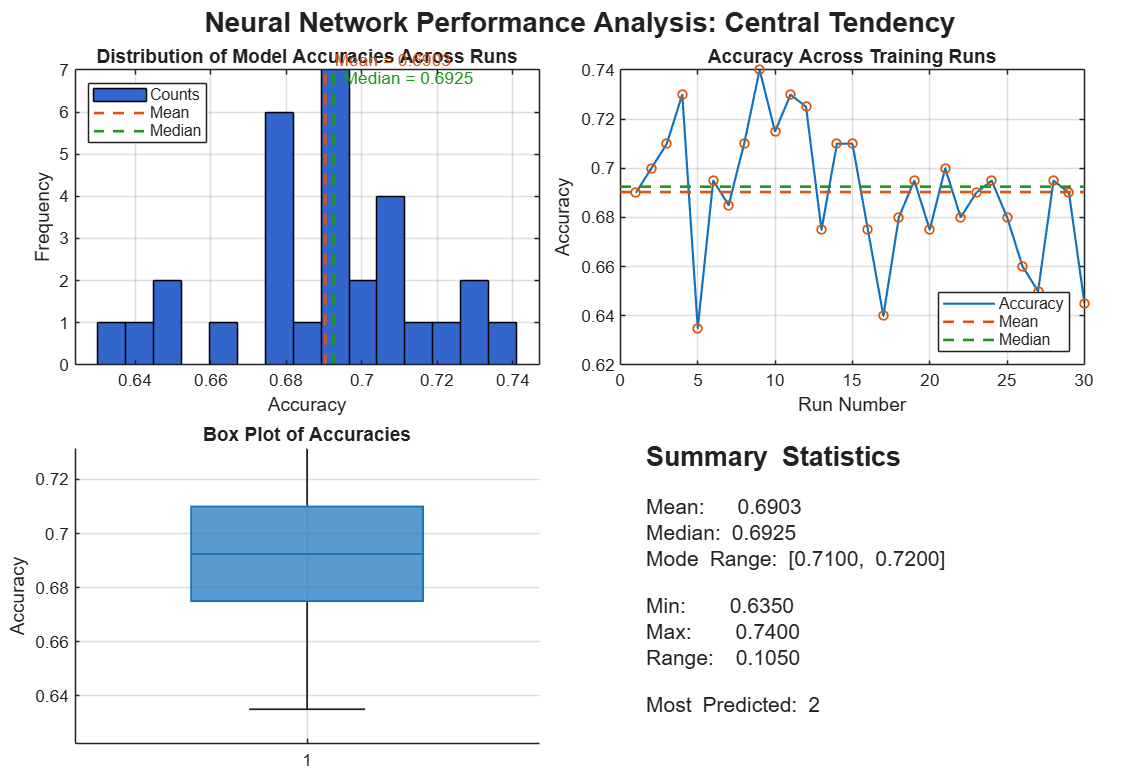

% Fast Visualization (MATLAB Online–friendly)

% ---- precompute once ----
nBins = 15;
[binCounts, binEdges] = histcounts(accuracies, nBins);
binCenters = (binEdges(1:end-1) + binEdges(2:end)) / 2;

cBlue   = [0.2, 0.4, 0.8];
cMean   = [0.85, 0.33, 0.10]; % reddish
cMedian = [0.10, 0.60, 0.10]; % greenish

% If runs are massive, thin plotted markers for speed (keeps lines full res)
runsFull = 1:numel(accuracies);
accFull  = accuracies(:).';
runsPlot = runsFull;
accPlot  = accFull;
maxMarkers = 1e4; % adjust if needed
if numel(runsFull) > maxMarkers
    ix = round(linspace(1, numel(runsFull), maxMarkers));
    runsPlot = runsFull(ix);
    accPlot  = accFull(ix);
end

% ---- layout ----
fig = figure('Position',[100,100,1100,750],'Color','w');
t = tiledlayout(fig,2,2,'TileSpacing','compact','Padding','compact');

% ---- Subplot 1: Accuracy distribution (bar from histcounts) ----
ax1 = nexttile(t,1);
b = bar(ax1, binCenters, binCounts, 'BarWidth', 1.0, ...
    'FaceColor', cBlue, 'EdgeColor', 'k');
hold(ax1,'on');
yl1 = ylim(ax1);

% mean/median lines (use low-level 'line' for speed)
hMean1   = line(ax1, [meanAccuracy meanAccuracy], yl1, ...
    'LineStyle','--','Color',cMean,'LineWidth',1.5,'HitTest','off');
hMedian1 = line(ax1, [medianAccuracy medianAccuracy], yl1, ...
    'LineStyle','--','Color',cMedian,'LineWidth',1.5,'HitTest','off');

% lightweight text labels (avoid xline/yline 'Label' overhead)
text(meanAccuracy, yl1(2), sprintf('  Mean = %.4f', meanAccuracy), ...
    'Parent',ax1,'VerticalAlignment','bottom','HorizontalAlignment','left', ...
    'Color',cMean,'FontSize',10,'Clipping','on');
text(medianAccuracy, yl1(2)-(yl1(2)-yl1(1))*0.06, sprintf('  Median = %.4f', medianAccuracy), ...
    'Parent',ax1,'VerticalAlignment','bottom','HorizontalAlignment','left', ...
    'Color',cMedian,'FontSize',10,'Clipping','on');

xlabel(ax1,'Accuracy'); ylabel(ax1,'Frequency');
title(ax1,'Distribution of Model Accuracies Across Runs');
grid(ax1,'on');

% Legend with explicit handles; disable auto-update for speed
lg1 = legend(ax1,[b hMean1 hMedian1], {'Counts','Mean','Median'}, 'Location','northwest');
set(lg1,'AutoUpdate','off');

% ---- Subplot 2: Accuracy across runs ----
ax2 = nexttile(t,2);
hData = plot(ax2, runsFull, accFull, '-', 'LineWidth', 1.25); % line only (fast)
hold(ax2,'on');
% draw sparse markers (fast) on thinned subset
plot(ax2, runsPlot, accPlot, 'o', 'LineWidth', 1.0, 'MarkerSize', 5);

xl2 = xlim(ax2);
hMean2   = line(ax2, xl2, [meanAccuracy meanAccuracy], 'LineStyle','--', ...
    'Color',cMean,'LineWidth',1.5,'HitTest','off');
hMedian2 = line(ax2, xl2, [medianAccuracy medianAccuracy], 'LineStyle','--', ...
    'Color',cMedian,'LineWidth',1.5,'HitTest','off');

xlabel(ax2,'Run Number'); ylabel(ax2,'Accuracy');
title(ax2,'Accuracy Across Training Runs'); grid(ax2,'on');
lg2 = legend(ax2,[hData hMean2 hMedian2], {'Accuracy','Mean','Median'}, 'Location','southeast');
set(lg2,'AutoUpdate','off');

% keep horizontal lines spanning full axes when you pan/zoom
addlistener(ax2,'XLim','PostSet',@(src,ev) set([hMean2 hMedian2],{'XData'},{ev.AffectedObject.XLim; ev.AffectedObject.XLim}));

% ---- Subplot 3: Box plot (tiledlayout-safe) ----
ax3 = nexttile(t,3);

boxchart(ax3, accuracies, ...
    'BoxFaceAlpha', 0.7, ...
    'MarkerStyle', 'none');

ylabel(ax3, 'Accuracy');
title(ax3, 'Box Plot of Accuracies');
grid(ax3, 'on');


% ---- Subplot 4: Summary ----
ax4 = nexttile(t,4);
axis(ax4,'off');

summaryText = {
    '\fontsize{14}\bfSummary Statistics';
    '';
    sprintf('Mean:   %.4f', meanAccuracy);
    sprintf('Median: %.4f', medianAccuracy);
    sprintf('Mode Range: [%.4f, %.4f]', modeAccuracyRange(1), modeAccuracyRange(2));
    '';
    sprintf('Min:    %.4f', min(accuracies));
    sprintf('Max:    %.4f', max(accuracies));
    sprintf('Range:  %.4f', range(accuracies));
    '';
    sprintf('Most Predicted: %s', string(modeClass))
};

text(ax4, 0.05, 0.55, summaryText, 'VerticalAlignment','middle', ...
    'FontSize',12, 'Interpreter','tex');

sgtitle(t,'Neural Network Performance Analysis: Central Tendency', ...
    'FontSize',16,'FontWeight','bold');


drawnow;  % a single flush at the very end

**What You Should See**

- Panel 1 (Histogram): Distribution of accuracies across 30 runs with mean (red dashed) and median (green dashed) lines overlaid. The histogram is slightly spread, indicating some variability in performance depending on initialization seed.

- Panel 2 (Line Plot): Accuracy progression across runs showing variability in model performance due to random initialization. Sharp rises and dips show the model’s sensitivity to initialization, where some runs find better minima than others. 

- Panel 3 (Box Plot): Shows median (center line), quartiles (box), and potential outliers (dots beyond whiskers).

- Panel 4 (Summary Statistics): Text display of all calculated central tendency measures and range information.

**Detailed Analysis**

1. Mean vs Median Comparison

- **If **`Mean ≈ Median`**:** The distribution is approximately symmetric. The model's performance is consistent across different initializations. 

- **If **`Mean < Median`**:** Left-skewed distribution. A few poor-performing runs (outliers) pull the mean down. The median better represents "typical" performance.

2. Mode Interpretation

- The mode range shows where most training runs converge. If the mode range is narrow and high (e.g., 0.71-0.72), it indicates that the model architecture and hyperparameters are well-suited for this problem, consistently achieving good performance regardless of initialization.

3. Variability Assessment

- The range (Max - Min) indicates sensitivity to initialization. A smaller range (e.g., 0.08) suggests stable training, while a larger range (e.g., > 0.15) indicates that some initializations lead to poor local minima. The range of ~0.10 shows moderate variability.

4. Most Predicted Class

- If one digit (e.g., "2") is predicted most frequently across all runs, it may indicate that this class is easiest to recognize or has unique features or the  model is biased slightly toward this class (Class 2 may be overrepresented or better learned). This mode analysis helps identify class-level patterns. 

**Practical Takeaways for AI Development**

✓ Choosing the Right Metric

- **Report Mean** when distribution is symmetric (no outliers)

- **Report Median** when outliers exist (more robust)

- **Report Both** to show distribution shape and variability

✓ Model Reliability

- Small difference between mean and median indicates reliable, stable training. Large differences suggest investigating why some runs fail (learning rate, initialization, data issues).

✓ Cross-Validation Strategy

- Multiple runs with different seeds simulate cross-validation. Central tendency measures help you understand expected performance and variance when deploying the model.

✓ Hyperparameter Tuning

- If mean accuracy is low but median is high, consider techniques like proper weight initialization, learning rate scheduling, or batch normalization to reduce sensitivity to initialization.

**Summary: Central Tendency in AI**

- Mean: Best for symmetric distributions without outliers. Provides expected performance but can be misleading with skewed data. Use for stable training scenarios.

- Median: Robust to outliers and provides typical performance. Essential when some training runs may fail or produce extreme results. Always report alongside mean.

- Mode: Shows most common outcomes. Useful for identifying convergence patterns and most frequently predicted classes. Requires binning for continuous data.

- Combined Analysis: Comparing all three measures reveals distribution shape (skewness) and helps assess model reliability. Large discrepancies indicate investigation needed.

Best Practice: Always report multiple central tendency measures and visualize the distribution to give a complete picture of model performance.

## **Practice Exercise**

Modify the code to train the network 50 times instead of 30. How do the central tendency measures change? Does the distribution become more symmetric?

Hint: Larger sample sizes typically produce more stable statistics and clearer distribution patterns.

# Section 2: Estimates of Variability

Understanding and measuring data spread to assess AI model reliability and prediction confidence.

**The Importance of Measuring Spread**

- Central tendency tells us the "typical" value, but variability tells us how much we can trust that typical value.

- Model Reliability: Two models with mean accuracy of 90% may have very different reliabilities. One with σ = 2% is consistent; one with σ = 15% is unreliable.

- Prediction Confidence: High variance in prediction probabilities indicates uncertainty. Low variance suggests confident predictions.

- Outlier Detection: IQR and standard deviation help identify anomalous predictions that may require human review.

- Feature Engineering: Coefficient of Variation helps compare variability across features with different scales (e.g., age vs. income).

## Variance

It measures the average squared deviation from the mean. It quantifies how spread out the data points are from the center.

Mathematical Formulas

- Population Variance (σ²):


$$\sigma ² =\frac{\Sigma (xᵢ - \mu )²}{N}$$


- Sample Variance (s²):


$$s² =\frac{\Sigma (xᵢ - x̄)²}{n - 1}$$


where **n-1** is used for unbiased sample variance ([Bessel's correction](https://www.statisticshowto.com/bessels-correction/)).

Let's get familiar with the MATLAB `var()` function:

x=[85,90,75,80,95,100];
fprintf('Variance of x: %.2f\n', var(x));

Variance of x: 87.50


✓ Properties:

- Always non-negative (≥ 0)

- Units are squared

- Sensitive to outliers

AI Use:

- Loss function variance

- Prediction uncertainty

- Feature variability

## Standard deviation

It is the square root of variance. It measures spread in the same units as the original data, making it more interpretable than variance.

Mathematical Formulas

- Population Standard Deviation ($\sigma$):


$$\sigma  = \sqrt{\sigma ²} = \sqrt{\frac{\Sigma (xᵢ - \mu )²}{N}}$$


- Sample Standard Deviation (s):


$$s = \sqrt{s²} = \sqrt{\frac{\Sigma (xᵢ - x̄)²}{n-1}}$$


Let's get familiar with the MATLAB `std()` function:

x=[85,90,75,80,95,100];
fprintf('Standard Deviation of x: %.2f\n', std(x));

Standard Deviation of x: 9.35


📏 Empirical Rule (for normal distributions):

- ~68% of data observations falls within $\mu  \pm  1\sigma $

- ~95% of data observations falls within $\mu  \pm  2\sigma $

- ~99.7% of data observations falls within $\mu  \pm  3\sigma $

✓ Advantages:

- Same units as data

- Interpretable scale

- Most commonly used

✗ Limitations:

- Sensitive to outliers

- Assumes meaningful mean

- Not scale-invariant

## Range

Tthe simplest measure of spread, calculated as the difference between the maximum and minimum values.

Mathematical Formula


$$\text{Range} = \max (x)-\min (x)$$


where $\max (x)$ is the largest value and $\min (x)$ is the smallest value

Let's get familiar with the MATLAB range`()` function:

x=[85,90,75,80,95,100];
fprintf('Range of x: %.2f\n', range(x));

Range of x: 25.00


✓ Advantages:

- Simple to calculate

- Easy to understand

- Quick overview of spread

✗ Limitations:

- Uses only 2 data points

- Extremely sensitive to outliers

- Ignores data distribution

AI Application:

Range is useful for understanding the full extent of model predictions (e.g., confidence scores from 0.1 to 0.99) but should be paired with more robust measures like IQR for outlier detection.

## Interquartile Range (IQR)

IQR measures the spread of the middle 50% of the data. It is the difference between the third quartile (Q3, 75th percentile) and the first quartile (Q1, 25th percentile).

Mathematical Formula

IQR = Q3 - Q1

**Q1 (First Quartile):** 25th percentile - 25% of data below this value

**Q2 (Second Quartile):** 50th percentile - the median

**Q3 (Third Quartile):** 75th percentile - 75% of data below this value

Outlier Detection Rule:

A data point is considered an outlier if:

- **Lower Outlier:** x < Q1 - 1.5 × IQR

- **Upper Outlier:** x > Q3 + 1.5 × IQR

Let's get familiar with the MATLAB `iqr() and quantile()` functions:

x=[85,90,75,80,95,100];
fprintf('Q1 of x: %.2f\n', quantile(x, 0.25));

Q1 of x: 80.00


fprintf('Q2 of x: %.2f\n', median(x));

Q2 of x: 87.50


fprintf('Q3 of x: %.2f\n', quantile(x, 0.75));

Q3 of x: 95.00


fprintf('IQR of x: %.2f\n', iqr(x)); %Q3-Q1

IQR of x: 15.00


✓ Advantages:

- Robust to outliers

- Focus on central data

- Good for skewed distributions

AI Use:

- Outlier detection

- Robust scaling

- Anomaly identification

## Coefficient of Variance (CV)

CV is a normalized measure of variability that expresses standard deviation as a percentage of the mean. It allows comparison of variability across datasets with different units or scales.

- Mathematical Formula


$$CV =\frac{\sigma }{\mu }\times  100%$$


- or for sample data:


$$\textrm{CV}=\frac{\sigma \;}{\bar{x} }\times 100$$


Interpretation Guidelines:

- **CV** **<** **15%:** Low variability (consistent data)

- **15% ≤ CV ≤ 30%:** Moderate variability

- **CV** **>** **30%:** High variability (inconsistent data)

Let's get familiar with the MATLAB steps for obtaining CV:

x = [85, 90, 75, 80, 95, 100];

% 1. Calculate the Mean (Average)
mu = mean(x);

% 2. Calculate the Standard Deviation (using the sample standard deviation, the default for std())
sigma = std(x);

% 3. Calculate the Coefficient of Variation (CV)
% Formula: CV = (Standard Deviation / Mean) * 100
CV_percentage = (sigma / mu) * 100;

% Display the results
fprintf('--- Statistical Metrics ---\n');

--- Statistical Metrics ---


fprintf('Data Mean (mu):              %.2f\n', mu);

Data Mean (mu):              87.50


fprintf('Standard Deviation (sigma):  %.2f\n', sigma);

Standard Deviation (sigma):  9.35


fprintf('---------------------------\n');

---------------------------


fprintf('Coefficient of Variation (CV): %.2f%%\n', CV_percentage);

Coefficient of Variation (CV): 10.69%



% Display a final interpretation
fprintf('\nInterpretation:\n');


Interpretation:


fprintf('The CV is %.2f%%. This means the standard deviation (spread) is %.2f%% of the mean value.\n', CV_percentage, CV_percentage);

The CV is 10.69%. This means the standard deviation (spread) is 10.69% of the mean value.


✓ Use When:

- Comparing different scales

- Assessing relative variability

- Mean is meaningful and > 0

✗ Avoid When:

- Mean is zero or near zero

- Data includes negative values

- Mean is not meaningful

## **AI Application Example**

This examples aim to analyze the variability in a neural network prediction confidence scores to assess model reliability and uncertainty. Therefore, we will train a neural network classifier and analyze the variability in prediction confidence scores to understand:

- **Standard Deviation:** Overall spread of confidence scores

- **Variance:** Quantify prediction uncertainty

- **Range:** Extreme confidence values (min to max)

- **IQR:** Robust measure of middle 50% spread and outlier detection

- **CV:** Relative variability to compare across classes

**Scenario**: Analyzing prediction confidence in an Image classification task.

**Analysis**: Identify uncertain predictions per-class confidence variability.

**Step 1: Load Data, Train Model & Get Predictions**

We load MNIST digits and train a CNN with deeper architecture (16 and 32 filters) for better feature learning. The seed ensures reproducibility of both data selection and weight initialization.

% Model Prediction Confidence Analysis
% Exercise: Estimates of Variability

clear; clc; close all;
%Note: Given this workbook contain many complex code,
% clear and clc are constantly used. Consequently, many data from
%previous code are not saved in the workspace.

% Set seed for reproducibility
rng(42);

% Load MNIST digit dataset
[XTrain, YTrain] = digitTrain4DArrayData;

% Use subset for faster training
numTrainSamples = 1000;
indices = randperm(size(XTrain, 4), numTrainSamples);
XTrain = XTrain(:,:,:,indices);
YTrain = YTrain(indices);

fprintf('=== DATASET INFORMATION ===\n');

=== DATASET INFORMATION ===


fprintf('Training samples: %d\n', size(XTrain, 4));

Training samples: 1000


fprintf('Classes: %d\n\n', length(unique(YTrain)));

Classes: 10




% Define CNN architecture
layers = [
    imageInputLayer([28 28 1])
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options = trainingOptions('adam', ...
    'MaxEpochs', 15, ...
    'MiniBatchSize', 64, ...
    'Verbose', false, ...
    'Plots', 'none');

fprintf('Training neural network...\n');

Training neural network...


net = trainNetwork(XTrain, YTrain, layers, options);
fprintf('Training complete!\n\n');

Training complete!



**Step 2: Get Test Predictions with Confidence Scores**

We obtain predictions and their corresponding confidence scores (probabilities from softmax layer). The maximum confidence for each prediction represents how certain the model is about its decision. We organize these scores by predicted class for detailed analysis.

% Load test data
[XTest, YTest] = digitTest4DArrayData;

% Use subset for analysis
numTestSamples = 500;
testIndices = randperm(size(XTest, 4), numTestSamples);
XTest = XTest(:,:,:,testIndices);
YTest = YTest(testIndices);

fprintf('Test samples: %d\n\n', size(XTest, 4));

Test samples: 500




% Get predictions with probability scores
[YPred, scores] = classify(net, XTest);

% Extract maximum confidence for each prediction
maxConfidence = max(scores, [], 2);

% Calculate accuracy
accuracy = sum(YPred == YTest) / numel(YTest);
fprintf('Test Accuracy: %.2f%%\n\n', accuracy * 100);

Test Accuracy: 89.60%




% Store confidence by class
classes = categories(YTest);
confidenceByClass = cell(length(classes), 1);

for i = 1:length(classes)
    classIdx = YPred == classes{i};
    confidenceByClass{i} = maxConfidence(classIdx);
end

**Step 3: Calculate All Variability Measures**

We compute all five variability measures on the confidence scores. The IQR method identifies predictions where the model had unusual confidence levels (either too low or too high), which may warrant further investigation.

fprintf('=== OVERALL CONFIDENCE STATISTICS ===\n');

=== OVERALL CONFIDENCE STATISTICS ===



% Calculate variability measures for all predictions
meanConf = mean(maxConfidence);
medianConf = median(maxConfidence);
stdConf = std(maxConfidence);
varConf = var(maxConfidence);
rangeConf = range(maxConfidence);
minConf = min(maxConfidence);
maxConf = max(maxConfidence);

% IQR calculation
Q1 = quantile(maxConfidence, 0.25);
Q3 = quantile(maxConfidence, 0.75);
iqrConf = Q3 - Q1;

% Outlier bounds
lowerBound = Q1 - 1.5 * iqrConf;
upperBound = Q3 + 1.5 * iqrConf;
outliers = maxConfidence < lowerBound | maxConfidence > upperBound;
numOutliers = sum(outliers);

% Coefficient of Variation
cvConf = (stdConf / meanConf) * 100;

% Display results
fprintf('Mean Confidence: %.4f\n', meanConf);

Mean Confidence: 0.8163


fprintf('Median Confidence: %.4f\n', medianConf);

Median Confidence: 0.8942


fprintf('Standard Deviation: %.4f\n', stdConf);

Standard Deviation: 0.1915


fprintf('Variance: %.6f\n', varConf);

Variance: 0.036656


fprintf('Range: %.4f [%.4f - %.4f]\n', rangeConf, minConf, maxConf);

Range: 0.7459 [0.2540 - 0.9999]


fprintf('IQR: %.4f [Q1=%.4f, Q3=%.4f]\n', iqrConf, Q1, Q3);

IQR: 0.2848 [Q1=0.6907, Q3=0.9755]


fprintf('Coefficient of Variation: %.2f%%\n', cvConf);

Coefficient of Variation: 23.45%


fprintf('Outliers detected: %d (%.1f%%)\n\n', numOutliers, ...
    (numOutliers/numTestSamples)*100);

Outliers detected: 1 (0.2%)



**Step 4: Analyze Variability by Class**

Per-class analysis reveals which digits the model predicts most consistently (low CV) and which show high uncertainty (high CV). This helps identify classes that may need more training data or better feature engineering.

fprintf('=== PER-CLASS CONFIDENCE STATISTICS ===\n');

=== PER-CLASS CONFIDENCE STATISTICS ===



classStats = struct();

for i = 1:length(classes)
    className = char(classes{i});
    conf = confidenceByClass{i};
    
    if ~isempty(conf)
        classStats(i).class = className;
        classStats(i).mean = mean(conf);
        classStats(i).std = std(conf);
        classStats(i).cv = (std(conf) / mean(conf)) * 100;
        classStats(i).iqr = iqr(conf);
        classStats(i).range = range(conf);
        classStats(i).count = length(conf);
        
        fprintf('\nClass %s (n=%d):\n', className, length(conf));
        fprintf('  Mean: %.4f, Std: %.4f\n', classStats(i).mean, ...
            classStats(i).std);
        fprintf('  CV: %.2f%%, IQR: %.4f, Range: %.4f\n', ...
            classStats(i).cv, classStats(i).iqr, classStats(i).range);
    end
end


Class 0 (n=40):


  Mean: 0.8309, Std: 0.1890


  CV: 22.75%, IQR: 0.2991, Range: 0.6140



Class 1 (n=37):


  Mean: 0.8834, Std: 0.1314


  CV: 14.87%, IQR: 0.1549, Range: 0.4661



Class 2 (n=52):


  Mean: 0.8229, Std: 0.1948


  CV: 23.67%, IQR: 0.3163, Range: 0.6537



Class 3 (n=57):


  Mean: 0.8139, Std: 0.2029


  CV: 24.93%, IQR: 0.2939, Range: 0.6652



Class 4 (n=45):


  Mean: 0.8596, Std: 0.1740


  CV: 20.24%, IQR: 0.2186, Range: 0.5912



Class 5 (n=47):


  Mean: 0.7596, Std: 0.1943


  CV: 25.58%, IQR: 0.3707, Range: 0.6769



Class 6 (n=58):


  Mean: 0.7963, Std: 0.1952


  CV: 24.51%, IQR: 0.2749, Range: 0.6869



Class 7 (n=65):


  Mean: 0.8674, Std: 0.1732


  CV: 19.97%, IQR: 0.1615, Range: 0.6376



Class 8 (n=43):


  Mean: 0.7512, Std: 0.2010


  CV: 26.75%, IQR: 0.3349, Range: 0.7445



Class 9 (n=56):


  Mean: 0.7819, Std: 0.2056


  CV: 26.30%, IQR: 0.3187, Range: 0.6702



% Find class with highest and lowest variability
cvValues = [classStats.cv];
[maxCV, maxCVIdx] = max(cvValues);
[minCV, minCVIdx] = min(cvValues);

fprintf('\n=== VARIABILITY COMPARISON ===\n');


=== VARIABILITY COMPARISON ===


fprintf('Most variable class: %s (CV=%.2f%%)\n', ...
    classStats(maxCVIdx).class, maxCV);

Most variable class: 8 (CV=26.75%)


fprintf('Least variable class: %s (CV=%.2f%%)\n', ...
    classStats(minCVIdx).class, minCV);

Least variable class: 1 (CV=14.87%)


**Step 5a: Overall Distribution Plots**

The first three plots show: (1) overall confidence distribution with quartiles, (2) box plot highlighting outliers, and (3) comparison of different variability measures to understand their relative magnitudes.

figure('Position',[100,100,1400,900],'Color','w');

%% Subplot 1: Histogram with statistics (fast: histcounts+bar, line+text)
ax1 = subplot(2,3,1);

% lightweight histogram
nBins = 30;
[counts,edges] = histcounts(maxConfidence(:), nBins);
centers = (edges(1:end-1)+edges(2:end))/2;

b1 = bar(ax1, centers, counts, 'BarWidth',1.0, ...
    'FaceColor',[0.5,0.2,0.8], 'EdgeColor','k');
hold(ax1,'on');
grid(ax1,'on');
xlabel(ax1,'Confidence Score');
ylabel(ax1,'Frequency');
title(ax1,'Distribution of Prediction Confidence');

% stats lines (replace xline labels with line+text for speed)
cMean   = [0.85 0.33 0.10];
cMedian = [0.10 0.60 0.10];
cQuart  = [0.10 0.35 0.80];

yl = ylim(ax1);
hMean   = line(ax1,[meanConf meanConf], yl, 'LineStyle','--','Color',cMean,  'LineWidth',1.5,'HitTest','off');
hMedian = line(ax1,[medianConf medianConf], yl,'LineStyle','--','Color',cMedian,'LineWidth',1.5,'HitTest','off');
hQ1     = line(ax1,[Q1 Q1], yl,           'LineStyle',':', 'Color',cQuart, 'LineWidth',1.2,'HitTest','off');
hQ3     = line(ax1,[Q3 Q3], yl,           'LineStyle',':', 'Color',cQuart, 'LineWidth',1.2,'HitTest','off');

% simple text labels at the top
yTop = yl(2);
text(ax1, meanConf,   yTop, sprintf('  Mean=%.3f',   meanConf),   'VerticalAlignment','bottom','Color',cMean);
text(ax1, medianConf, yTop-0.06*(yTop-yl(1)), sprintf('  Median=%.3f', medianConf), 'VerticalAlignment','bottom','Color',cMedian);
text(ax1, Q1,         yTop-0.12*(yTop-yl(1)), sprintf('  Q1=%.3f',     Q1),        'VerticalAlignment','bottom','Color',cQuart);
text(ax1, Q3,         yTop-0.18*(yTop-yl(1)), sprintf('  Q3=%.3f',     Q3),        'VerticalAlignment','bottom','Color',cQuart);

% keep lines spanning x-range on pan/zoom
addlistener(ax1,'YLim','PostSet',@(~,ev) set([hMean hMedian hQ1 hQ3],{'YData'},{ev.AffectedObject.YLim;ev.AffectedObject.YLim;ev.AffectedObject.YLim;ev.AffectedObject.YLim}));

lg1 = legend(ax1,[b1 hMean hMedian hQ1 hQ3],{'Counts','Mean','Median','Q1','Q3'},'Location','northwest');
set(lg1,'AutoUpdate','off');

%% Subplot 2: Box plot with outliers (tiled-safe: use boxchart)
ax2 = subplot(2,3,2);
g = ones(numel(maxConfidence),1);
boxchart(ax2, g, maxConfidence(:), 'MarkerStyle','.', 'BoxFaceAlpha',0.8);
ax2.XTick = [];  % single group, hide tick
ylabel(ax2,'Confidence Score');
title(ax2, sprintf('Box Chart (IQR=%.4f, Outliers=%d)', iqrConf, numOutliers));
grid(ax2,'on');

%% Subplot 3: Variability measures comparison (categorical bars for labels)
ax3 = subplot(2,3,3);
measures = [stdConf; iqrConf; rangeConf; cvConf/100];
names = categorical({'Std Dev','IQR','Range','CV (scaled)'});
names = reordercats(names, cellstr(names));  % keep order

bar(ax3, names, measures, 'FaceColor',[0.3,0.6,0.8], 'EdgeColor','k');
ylabel(ax3,'Value');
title(ax3,'Variability Measures Comparison');
grid(ax3,'on');

% (Optional) a single final flush is cheaper
% drawnow limitrate

**Step 5b: Per-Class Analysis Plots**

These plots reveal per-class patterns: which classes have consistent confidence (low CV), the relationship between mean confidence and variability, and a comprehensive summary of all calculated measures.

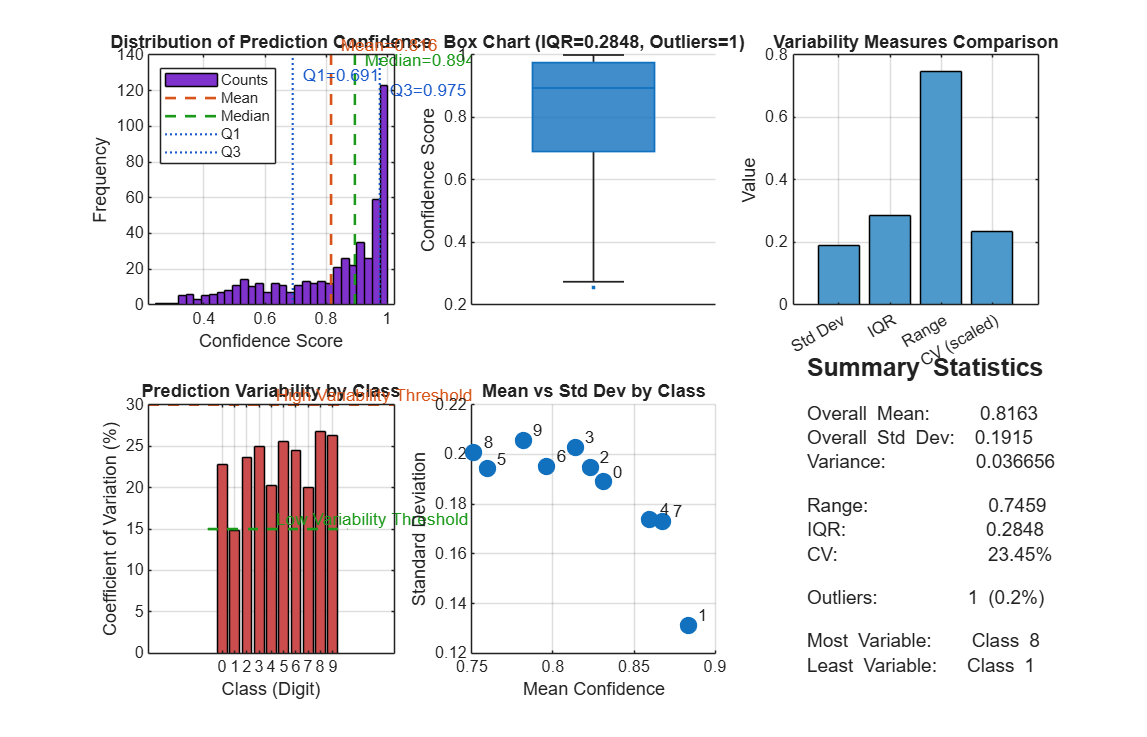

% ---------- Subplot 4: Per-class CV comparison (fast, explicit handles) ----------
ax4 = subplot(2,3,4);

classNames = {classStats.class};
cvByClass  = [classStats.cv];

b4 = bar(ax4, cvByClass, 'FaceColor', [0.8, 0.3, 0.3], 'EdgeColor','k');
hold(ax4,'on');

% Efficient tick labels
set(ax4, 'XTick', 1:numel(classNames));
xticklabels(ax4, classNames);
xlabel(ax4, 'Class (Digit)');
ylabel(ax4, 'Coefficient of Variation (%)');
title(ax4, 'Prediction Variability by Class');
grid(ax4,'on');

% Replace yline(...) with lightweight line+text
yl = ylim(ax4);
hLow  = line(ax4, xlim(ax4), [15 15], 'LineStyle','--', 'Color',[0.10 0.60 0.10], 'LineWidth',1.5, 'HitTest','off');
hHigh = line(ax4, xlim(ax4), [30 30], 'LineStyle','--', 'Color',[0.85 0.33 0.10], 'LineWidth',1.5, 'HitTest','off');
text(ax4, mean(xlim(ax4)), 15,  ' Low Variability Threshold',  'VerticalAlignment','bottom','HorizontalAlignment','left','Color',[0.10 0.60 0.10]);
text(ax4, mean(xlim(ax4)), 30,  ' High Variability Threshold', 'VerticalAlignment','bottom','HorizontalAlignment','left','Color',[0.85 0.33 0.10]);

% Keep threshold lines spanning full x-range when pan/zoom
addlistener(ax4,'XLim','PostSet', @(~,ev) set([hLow hHigh], {'XData'}, {ev.AffectedObject.XLim; ev.AffectedObject.XLim}));


% ---------- Subplot 5: Mean vs Std by class ----------
ax5 = subplot(2,3,5);
meanByClass = [classStats.mean];
stdByClass  = [classStats.std];

s5 = scatter(ax5, meanByClass, stdByClass, 100, 'filled'); % few points -> fine
xlabel(ax5, 'Mean Confidence');
ylabel(ax5, 'Standard Deviation');
title(ax5, 'Mean vs Std Dev by Class');
grid(ax5,'on');

% Label each point (use classNames, not undefined 'classes')
nC = numel(classNames);
for i = 1:nC
    text(ax5, meanByClass(i), stdByClass(i), ['  ' char(string(classNames{i}))], ...
        'VerticalAlignment','bottom','HorizontalAlignment','left', ...
        'Clipping','on');
end


% ---------- Subplot 6: Summary text (fix cell array shape) ----------
ax6 = subplot(2,3,6);
axis(ax6,'off');

summaryText = {
    '\fontsize{13}\bfSummary Statistics';
    '';
    sprintf('Overall Mean:     %.4f', meanConf);
    sprintf('Overall Std Dev:  %.4f', stdConf);
    sprintf('Variance:         %.6f', varConf);
    '';
    sprintf('Range:            %.4f', rangeConf);
    sprintf('IQR:              %.4f', iqrConf);
    sprintf('CV:               %.2f%%', cvConf);
    '';
    sprintf('Outliers:         %d (%.1f%%)', numOutliers, (numOutliers/numTestSamples)*100);
    '';
    sprintf('Most Variable:    Class %s', char(string(classStats(maxCVIdx).class)));
    sprintf('Least Variable:   Class %s', char(string(classStats(minCVIdx).class)))
};

text(ax6, 0.05, 0.55, summaryText, 'VerticalAlignment','middle', ...
     'FontSize',11, 'Interpreter','tex');


% (Optional) one flush at the end is cheaper
% drawnow limitrate

**Key Observations**

- Moderate Mean Confidence (~0.82): The model is confident on average but not highly certain. Confidence is not uniformly strong across all predictions.

- High CV (~23%): Relative variability is moderate to high, indicating confidence levels fluctuate significantly between samples.

- IQR vs Range: A wide overall range (0.75) compared to a moderate IQR (0.28) suggests the presence of extreme low-confidence outliers (uncertain predictions).

**Understanding the Variability Measures**

1. Standard Deviation & Variance

- Std Dev ≈ 0.19: Confidence scores typically deviate from the mean by about 19 percentage points, which reflects substantial fluctuation.

- Variance ≈ 0.0366: Indicates meaningful dispersion. While variance is mathematically useful, the high standard deviation already signals inconsistency.

- AI Insight: Unlike a tightly clustered model, this one produces both strong and weak confidence scores. Some predictions may fall around 0.60 or below, indicating uncertainty or confusion.

2. Range Analysis

- Range ≈ 0.746 (≈ 0.25 → 1.00): Extremely wide spread — the model oscillates between near-total uncertainty and complete confidence.

- AI Insight: This model is not uniformly sure of what it predicts. Wide range indicates the model has very different confidence levels across samples. Some predictions are highly certain while others are borderline guesses. Investigate low-confidence predictions for potential misclassifications.

3. IQR (Robust Measure)

- IQR ≈ 0.2848: The middle 50% of predictions have confidence scores within a ~0.28 range. Much smaller than overall range (0.746).

- AI Insight: The large gap between IQR (0.28) and Range (0.75) confirms the presence of outliers — some predictions with very low confidence that may be errors or difficult cases.

**CV and Per-Class Analysis**

4. Coefficient of Variation (CV)

**CV ≈ 23%:** Standard deviation is only 23% of the mean. This is LOW variability.


$$CV = (\frac{\sigma }{\mu })\times100\% = (\frac{0.1915}{0.8163})\times100\% \approx23.46\%$$


**Interpretation Guidelines:**

- CV < 15% → Low variability

- 15% ≤ CV ≤ 30% → Moderate variability (*Our case*)

- CV > 30% → High variability ️

**AI Insight:** This model does not deliver uniformly consistent confidence. Confidence levels vary considerably between samples and classes.

5. Per-Class Variability

Some digits are easier to classify than others, revealed by CV differences:

- **Low CV classes (e.g., "1", "0"):** Distinctive features, consistent high confidence

- **High CV classes (e.g., "8", "5"):** Ambiguous features, variable confidence

**AI Insight:** Classes with high CV need attention:

- More training data for that class

- Better feature engineering

- Data augmentation strategies

6. Outlier Detection

Using IQR method: Outliers = predictions with confidence `< Q1 - 1.5×IQR` or `> Q3 + 1.5×IQR`

**AI Insight:** Outliers represent predictions where model confidence was unusually low (or high). Review these cases manually – they may be mislabeled data, edge cases, or genuinely difficult samples requiring human verification.

**Summary: Variability Measures in AI**

- **Variance & Standard Deviation: **Measure the *overall spread* of confidence scores. Standard deviation (same units as the data) is easier to interpret — here, it reveals substantial fluctuation (~0.19) around the mean. Variance supports mathematical comparisons but is less intuitive. Both remain **sensitive to extreme low-confidence cases**.

- **Range: **Provides a quick view of the *extremes*, from highly confident to highly uncertain predictions. A wide range (~0.75) indicates the model occasionally produces very low confidence outputs, signalling inconsistency or challenging samples. Useful for spotting instability but not robust on its own. Therefore, it is good for initial assessment but pair it with robust measures.

- **Interquartile Range (IQR): **A *robust measure* of spread focused on the middle 50% of predictions. The IQR (~0.28) shows notable variation even within the central region. The large gap between IQR and range confirms **existence of true outliers** — critical for understanding model uncertainty under difficult cases.

- **Coefficient of Variation (CV): **A *scale-normalized indicator* of reliability. With CV ≈ 23%, this model exhibits **moderate-to-high variability**, meaning confidence levels vary meaningfully across samples or classes. Unlike low-CV models (<15%), this one requires per-class scrutiny and possible calibration.

**Integration with Central Tendency**

Variability measures are meaningless without central tendency. Always report together:

`"Model achieved 95% ± 8% confidence (mean ± std dev, CV = 8.4%)"`

This gives complete picture: where predictions centre (mean) and how much they spread (variability).

## Practice Exercise

Modify the code to analyze confidence variability for correct vs. incorrect predictions separately. How do the variability measures differ?

Hint: Split predictions into correct (YPred == YTest) and incorrect, then calculate all variability measures for each group. This reveals if model is overconfident in errors.

# Section 3: Correlation

Understanding relationships between variables for feature selection and multicollinearity detection in AI models.

**The Importance of Understanding Relationships**

Correlation reveals how variables move together, critical for building efficient and interpretable AI models. Therefore, correlation can help with:

- Feature Selection: Highly correlated features are redundant. Remove one to reduce dimensionality without losing information. Speeds up training and reduces overfitting.

- Multicollinearity Detection: When features are highly correlated (r > 0.8), linear models produce unstable coefficients. Correlation matrices help identify and remove collinear features.

- Feature Engineering: Correlation with target variable guides feature creation. Features with high `|r|` with target are informative. Low correlation suggests feature may not be useful.

- Model Interpretability: Understanding feature relationships helps explain model predictions. Correlated features should be interpreted together, not in isolation.

## The Pearson correlation coefficient (r)

The r coefficient measures the strength and direction of the linear relationship between two continuous variables. It ranges from `-1 to +1`.

Mathematical Formula


$$r_{xy}=\frac{\Sigma(x_i - \bar{x})(y_i - \bar{y})}{\sqrt{[\Sigma(x_i - \bar{x})²]} \cdot  \sqrt{\Sigma(y_i-\bar{y})²]}}$$


Alternative form (using covariance):


$$r_{xy} =\frac{Cov(X, Y)}{\sigma_x\cdot \sigma_y}$$


where **Cov(X,Y)** is covariance, $\sigma _x$ and $\sigma _y$ are standard deviations

- $r = -1$: Perfect negative linear relationship

- $r = 0$: No linear relationship

- $r = +1$: Perfect positive linear relationship

The absolute value $|r|$indicates strength; the sign indicates direction (positive or negative relationship).

Interpretation Scale

- $|r| \ge  0.9$**: **Very Strong Correlation

- $0.7\leq|r|\lt0.9$: Strong Correlation

- $0.5\leq|r|\lt0.7$: Moderate Correlation

- $0.3\leq|r|\lt0.5$: Weak Correlation

- $|r|\lt0.3$: Very Weak/Negligible

Important Caveats:

- Correlation ≠ Causation ($r$ just measures association)

- Only captures linear relationships

- Sensitive to outliers

- Context matters: $r = 0.5$ might be strong in social sciences, weak in physics

✓ In AI/ML Context:

- `|r| > 0.8`: Consider removing redundant feature

- `|r| with target > 0.5`: Strong predictor

- `|r| with target < 0.1`: Likely not useful

Properties:

- Dimensionless (no units)

- Symmetric: $r_{xy} = r_{xy}$

- Invariant to scale changes

## A correlation matrix

This matrix is a symmetric matrix showing correlation coefficients between all pairs of variables. The diagonal is always 1 (a variable perfectly correlates with itself).

Matrix Structure

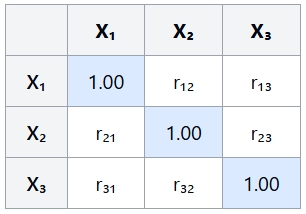

Note: $r_{ij} = r_{ij}$ (symmetric matrix)

**MATLAB function**: `corrMatrix = corr(featureMatrix);`

Creates correlation matrix for all column pairs in the feature matrix.

- Visualization: Heatmaps are ideal for correlation matrices. Color intensity shows strength; color hue shows direction (e.g., red = positive, blue = negative).

- Usage: Quickly identify feature pairs with |r| > threshold (e.g., 0.8) to detect multicollinearity.

### What is Multicollinearity?

Multicollinearity occurs when two or more predictor variables are highly correlated with each other. This creates problems for linear models (e.g., regression, logistic regression, linear SVMs).

**Problems Caused by Multicollinearity**

- Unstable Coefficients: Small changes in data lead to large changes in model coefficients. Makes interpretation unreliable.

- Inflated Standard Errors: Larger confidence intervals for coefficients. Harder to determine which features are truly significant.

- Reduced Model Interpretability: Can't isolate individual feature effects. E.g., if height and weight are correlated, can't say "height increases by 1 cm → outcome changes by X."

- Overfitting Risk: Redundant features increase model complexity without adding information. More parameters = higher overfitting risk.

**✓ Detection Threshold:** Features with `|r| > 0.8 or 0.9` indicate problematic multicollinearity. Remove one feature from each highly correlated pair.

**Model Dependency:** Tree-based models (Random Forest, XGBoost) handle multicollinearity well. Neural networks are moderately affected.

## **AI Application Example**

This exercise aim to analyze feature correlations in a house price dataset to detect multicollinearity and perform feature selection. Therefore, we will build a realistic house price dataset with multiple features and analyze correlations to:

- **Calculate correlation matrix:** All pairwise feature correlations

- **Detect multicollinearity:** Identify highly correlated feature pairs (|r| > 0.8)

- **Target correlation:** Find features most correlated with house price

- **Feature selection:** Remove redundant features to improve model

- **Visualize relationships:** Heatmaps and scatter plots

**Dataset Features**: Size, bedrooms, bathrooms, age, distance to city, garage, lot size.

**Analysis Goals**: Find redundancies, identify best predictors, optimize feature set.

**Step 1: Create House Price Dataset**

We create a synthetic dataset with realistic correlations. House size correlates with bedrooms, bathrooms, and lot size (as in real life). Price depends on all features with added noise for realism.

% Feature Correlation Analysis for House Price Prediction

clear; clc; close all;

% Set seed for reproducibility
rng(42);

% Generate synthetic house price dataset
n = 500;

% Feature 1: House size (square feet)
houseSize = 1000 + 2500 * rand(n, 1);

% Feature 2: Number of bedrooms (correlated with size)
bedrooms = round(2 + (houseSize - 1000) / 600);
bedrooms = max(1, min(bedrooms, 6));

% Feature 3: Number of bathrooms (correlated with bedrooms and size)
bathrooms = round(1 + bedrooms * 0.5 + 0.3 * randn(n, 1));
bathrooms = max(1, min(bathrooms, 5));

% Feature 4: House age (years)
houseAge = randi([0, 50], n, 1);

% Feature 5: Distance to city center (km)
distanceToCity = 5 + 25 * rand(n, 1);

% Feature 6: Garage spaces (somewhat correlated with bedrooms)
garageSpaces = round(bedrooms * 0.5 + 0.5 * randn(n, 1));
garageSpaces = max(0, min(garageSpaces, 4));

% Feature 7: Lot size (correlated with house size)
lotSize = houseSize * 0.8 + 500 * randn(n, 1);
lotSize = max(lotSize, 1000);

% Target: House price (depends on multiple features)
basePrice = 50000;
pricePerSqFt = 150;
bedroomValue = 20000;
bathroomValue = 15000;
agePenalty = -1000;
distancePenalty = -2000;
garageValue = 10000;
lotSizeValue = 30;

price = basePrice + pricePerSqFt * houseSize + ...
        bedroomValue * bedrooms + bathroomValue * bathrooms + ...
        agePenalty * houseAge + distancePenalty * distanceToCity + ...
        garageValue * garageSpaces + lotSizeValue * lotSize + ...
        50000 * randn(n, 1);

price = max(price, 100000);

fprintf('=== DATASET CREATED ===\n');

=== DATASET CREATED ===


fprintf('Number of samples: %d\n', n);

Number of samples: 500


fprintf('Number of features: 7\n\n');

Number of features: 7



**Step 2: Calculate Correlation Matrix**

The `corr()` function computes all pairwise correlations efficiently. We then identify pairs with `|r| > 0.8`, which indicates potential multicollinearity. These pairs are candidates for feature removal.

% Combine all variables into a single data matrix
dataMatrix = [houseSize, bedrooms, bathrooms, houseAge, distanceToCity, garageSpaces, lotSize, price];
featureNames = {'Size (sqft)', 'Bedrooms', 'Bathrooms', 'Age (yrs)', 'Dist. to City', 'Garage', 'Lot Size', 'Price'};


% --- 2. PEARSON CORRELATION (Linear Relationship) ---

% Calculate Pearson correlation matrix
R_Pearson = corr(dataMatrix, 'Type', 'Pearson');

fprintf('====================================================\n');

fprintf('               PEARSON CORRELATION MATRIX (R)\n');

               PEARSON CORRELATION MATRIX (R)


fprintf('====================================================\n');

disp(array2table(R_Pearson, 'VariableNames', featureNames, 'RowNames', featureNames));

                     Size (sqft)     Bedrooms     Bathrooms    Age (yrs)    Dist. to City     Garage      Lot Size      Price  
                     ___________    __________    _________    _________    _____________    _________    ________    _________

    Size (sqft)               1        0.97795       0.8121     0.031137      -0.018529        0.73632     0.75146      0.94801
    Bedrooms            0.97795              1      0.84321      0.03086     -0.0055262        0.75889     0.73673      0.94041
    Bathrooms            0.8121        0.84321            1     0.041743      0.0080194        0.61001     0.60404       0.7983
    Age (yrs)      



% --- 3. SPEARMAN CORRELATION (Monotonic Relationship) ---

% Calculate Spearman rank correlation matrix
R_Spearman = corr(dataMatrix, 'Type', 'Spearman');

fprintf('====================================================\n');

fprintf('              SPEARMAN CORRELATION MATRIX (rho)\n');

              SPEARMAN CORRELATION MATRIX (rho)


fprintf('====================================================\n');

disp(array2table(R_Spearman, 'VariableNames', featureNames, 'RowNames', featureNames));

                     Size (sqft)     Bedrooms     Bathrooms     Age (yrs)    Dist. to City     Garage      Lot Size      Price  
                     ___________    __________    __________    _________    _____________    _________    ________    _________

    Size (sqft)               1        0.97838       0.82056     0.034737      -0.020225        0.74121      0.7687      0.94987
    Bedrooms            0.97838              1       0.84992     0.030615     -0.0041658        0.76442      0.7546      0.94416
    Bathrooms           0.82056        0.84992             1     0.036532     -0.0016989        0.61831     0.63705      0.80901
    Age (yrs)    

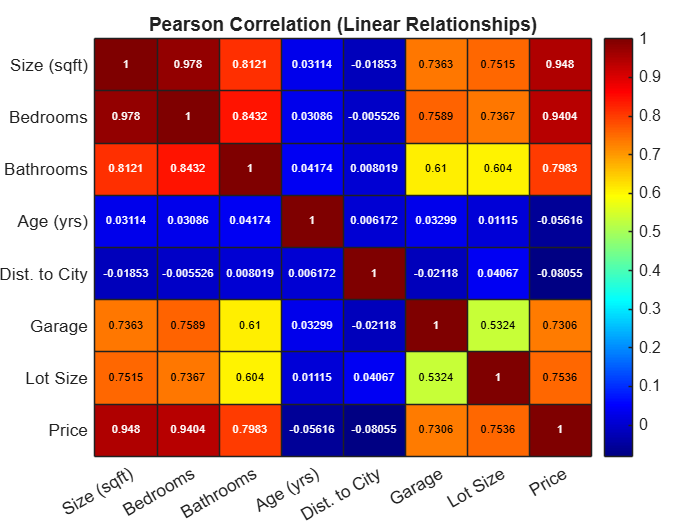



% --- 4. VISUALIZATION ---

% Figure 1: Heatmap for Pearson Correlation
figure('Name', 'Pearson Correlation Heatmap');
h_pearson = heatmap(featureNames, featureNames, R_Pearson);
h_pearson.Title = 'Pearson Correlation (Linear Relationships)';
h_pearson.FontSize = 10;
colormap(jet); % Use jet or other color map
colorbar;

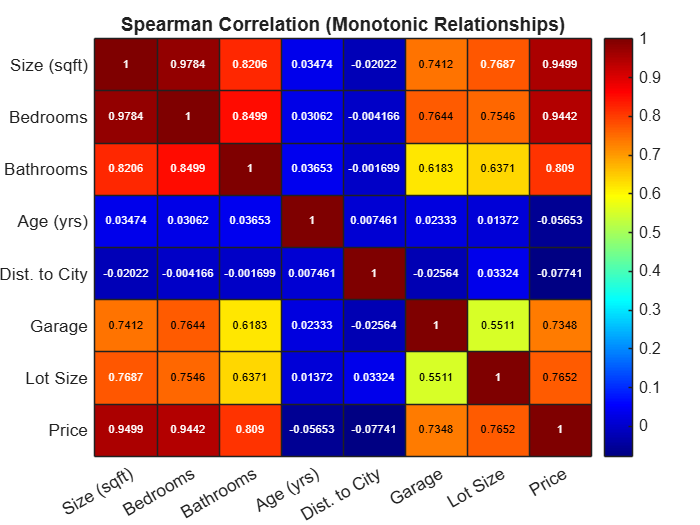



% Figure 2: Heatmap for Spearman Correlation
figure('Name', 'Spearman Correlation Heatmap');
h_spearman = heatmap(featureNames, featureNames, R_Spearman);
h_spearman.Title = 'Spearman Correlation (Monotonic Relationships)';
h_spearman.FontSize = 10;
colormap(jet); % Use jet or other color map
colorbar;


% Calculate correlation matrix for features again
corrMatrix = corr(dataMatrix);

% Identify highly correlated pairs (multicollinearity)
threshold = 0.8;
[row, col] = find(abs(corrMatrix) > threshold & corrMatrix < 1);

fprintf('High Correlation Pairs (|r| > %.2f):\n', threshold);

High Correlation Pairs (|r| > 0.80):


if isempty(row)
    fprintf('  None found.\n');
else
    for k = 1:length(row)
        if row(k) < col(k)
            fprintf('  %s <-> %s: r = %.3f\n', ...
                featureNames{row(k)}, featureNames{col(k)}, ...
                corrMatrix(row(k), col(k)));
        end
    end
end

  Size (sqft) <-> Bedrooms: r = 0.978
  Size (sqft) <-> Bathrooms: r = 0.812
  Bedrooms <-> Bathrooms: r = 0.843
  Size (sqft) <-> Price: r = 0.948
  Bedrooms <-> Price: r = 0.940


fprintf('\n');

**Step 3: Correlation with Target (Price)**

We calculate correlation between each feature and the target variable (price). Features with high `|r|` are strong predictors. Features with very low `|r|` (e.g., < 0.1) may not be useful and could be removed.

% Calculate correlation of each feature with price
priceCorrelations = zeros(length(featureNames), 1);
for i = 1:length(featureNames)-1
    priceCorrelations(i) = corr(dataMatrix(:,i), price);
end

% Sort by absolute correlation strength
[sortedAbsCorr, sortIdx] = sort(abs(priceCorrelations), 'descend');
sortedCorr = priceCorrelations(sortIdx);
sortedNames = featureNames(sortIdx);

fprintf('=== CORRELATION WITH PRICE (Sorted by Strength) ===\n');

=== CORRELATION WITH PRICE (Sorted by Strength) ===


for i = 1:length(sortedNames)-1
    strength = '';
    absVal = abs(sortedCorr(i));
    if absVal >= 0.7
        strength = '(Strong)';
    elseif absVal >= 0.5
        strength = '(Moderate)';
    elseif absVal >= 0.3
        strength = '(Weak)';
    else
        strength = '(Very Weak)';
    end
    
    fprintf('%d. %-25s r = %+.4f %s\n', i, sortedNames{i}, ...
        sortedCorr(i), strength);
end

1. Size (sqft)               r = +0.9480 (Strong)
2. Bedrooms                  r = +0.9404 (Strong)
3. Bathrooms                 r = +0.7983 (Strong)
4. Lot Size                  r = +0.7536 (Strong)
5. Garage                    r = +0.7306 (Strong)
6. Dist. to City             r = -0.0806 (Very Weak)
7. Age (yrs)                 r = -0.0562 (Very Weak)


fprintf('\n');

% Identify best predictors
strongPredictors = find(abs(priceCorrelations) > 0.5);
fprintf('Strong Predictors (|r| > 0.5): %d features\n', ...
    length(strongPredictors));

Strong Predictors (|r| > 0.5): 5 features


for i = 1:length(strongPredictors)
    idx = strongPredictors(i);
    fprintf('  - %s (r = %.3f)\n', featureNames{idx}, ...
        priceCorrelations(idx));
end

  - Size (sqft) (r = 0.948)
  - Bedrooms (r = 0.940)
  - Bathrooms (r = 0.798)
  - Garage (r = 0.731)
  - Lot Size (r = 0.754)


fprintf('\n');

**Typical Output Patterns**

Results depend on the synthetic data generation but follow predictable patterns.

Expected Correlation Patterns

High Positive Correlations (`r ≈ 0.8-0.95`)

- **House Size ↔ Lot Size:** Bigger houses typically on bigger lots

- **House Size ↔ Bedrooms:** Larger homes have more bedrooms

- **Bedrooms ↔ Bathrooms:** More bedrooms usually mean more bathrooms

Moderate Correlations (`r ≈ 0.4-0.7`)

- **Bedrooms ↔ Garage:** Partial relationship

- **Bathrooms ↔ House Size:** Related but with variation

Low/Negative Correlations (`|r| ≈ 0.0-0.3`)

- **Age ↔ Size:** Old houses can be any size

- **Distance to City ↔ Age:** Independent variables

- **Price ↔ Age:** Negative (older = cheaper)

- **Price ↔ Distance:** Negative (farther = cheaper)

**2-3: **HIGH CORRELATION PAIRS - `|r| > 0.8`

**4-5: **STRONG PREDICTORS - `|r| > 0.5` with price

**1-2: **FEATURES TO REMOVE - Redundant or weak

**Understanding the Correlation Matrix**

1. Identifying Multicollinearity

**Example Finding:** House Size and Lot Size have `r ≈ 0.92`

**Interpretation:** These features are nearly interchangeable – knowing one tells you almost everything about the other. This is problematic multicollinearity.

**Action:** Check which has higher correlation with price:

- If House Size: `r(price) = 0.85`, Lot Size: `r(price) = 0.68`

- **Decision:** Remove Lot Size, keep House Size

- **Rationale:** House Size is a better predictor and more directly related to price

2. Correlation with Target (Price)

**Typical Rankings:**

- House Size: `r = +0.85`

- Lot Size: `r = +0.68`

- Bedrooms: `r = +0.52`

- Distance to City: `r = -0.45`

- Age: `r = -0.32`

**Interpretation:** House Size is the strongest predictor (positive correlation). Distance and Age have negative correlations (as expected – farther/older = cheaper).

**Practical Takeaways for AI Development**

✓ Model Selection Based on Multicollinearity

**High multicollinearity detected:**

- ✗ Avoid: Linear Regression, Logistic Regression (unstable coefficients)

- ✓ Consider: Ridge/Lasso Regression (regularization handles it)

- ✓ Consider: Tree-based models (Random Forest, XGBoost – handle naturally)

- ✓ Best: Remove redundant features before modeling

✓ Feature Engineering Guidance

**Create interaction features** for moderately correlated variables (`0.3 < r < 0.7`). Example: Bedrooms × Bathrooms may capture "luxury" better than either alone. **Avoid** for highly correlated features (redundant information).

✓ Reporting Best Practices

Always include correlation matrix in EDA reports. Document which features were removed and why. Report both feature-feature and feature-target correlations. Justify feature selection decisions quantitatively.

# Section 4: Applying Descriptive Statistics to MATLAB Datasets

Let's summarise all the above concepts by verifying the descriptive statistics and correlation on the Fisher Iris Dataset and Patient Dataset.

**Datasets Used in This Tutorial**

**1. Fisher's Iris Dataset**

- **Domain:** Botanical classification

- **Size:** 150 observations

- **Features:** 4 continuous measurements (sepal length, sepal width, petal length, petal width)

- **Target:** 3 species classes (setosa, versicolor, virginica)

- **AI Application Context:** This is a classic multi-class classification problem, perfectly balanced with 50 samples per class. It demonstrates sampling challenges when working with structured, labeled data.

- **Why this dataset?** The Iris dataset's perfect class balance allows us to observe how different sampling methods preserve or distort this balance, which is critical for classification tasks.

**2. Patients Medical Dataset**

- **Domain:** Healthcare analytics

- **Size:** 100 observations

- **Features:** 7 variables including demographics (Age, Gender), physical measurements (Height, Weight), vital signs (Systolic/Diastolic blood pressure), and behavioral factors (Smoker status)

- **Mixed data types:** Continuous numerical and categorical variables

- **AI Application Context:** Represents real-world healthcare data used in predictive modeling for patient risk assessment, diagnosis support, and treatment planning.

- **Why this dataset?** The mixed data types and natural groupings (by gender, age ranges) demonstrate how sampling strategies must adapt to different data structures commonly encountered in AI applications.

clear; clc; close all;

%% ---------- 1) IRIS ----------
disp('===== IRIS DATASET =====')

===== IRIS DATASET =====


load fisheriris
irisTbl = array2table(meas, ...
    'VariableNames', {'SepalLength','SepalWidth','PetalLength','PetalWidth'});

% Descriptive Statistics
irisDesc = describeTable(irisTbl);
disp(irisDesc)

             SepalLength    SepalWidth    PetalLength    PetalWidth
             ___________    __________    ___________    __________

    count          150           150           150            150  
    mean        5.8433        3.0573         3.758         1.1993  
    std        0.82807       0.43587        1.7653        0.76224  
    min            4.3             2             1            0.1  
    25%            5.1           2.8           1.6            0.3  
    50%            5.8             3          4.35            1.3  
    75%            6.4           3.3           5.1            1.8  
    max            7.9           4.4           6.9            2.5  




% Correlation (pairwise to be safe with NaNs; Iris has none)
[C_iris, p_iris] = corrcoef(table2array(irisTbl), 'Rows','pairwise');
disp('--- Iris Correlation Matrix ---');  disp(array2table(C_iris, ...
    'VariableNames', irisTbl.Properties.VariableNames, ...
    'RowNames', irisTbl.Properties.VariableNames));

--- Iris Correlation Matrix ---
                   SepalLength    SepalWidth    PetalLength    PetalWidth
                   ___________    __________    ___________    __________

    SepalLength            1       -0.11757       0.87175        0.81794 
    SepalWidth      -0.11757              1      -0.42844       -0.36613 
    PetalLength      0.87175       -0.42844             1        0.96287 
    PetalWidth       0.81794       -0.36613       0.96287              1 



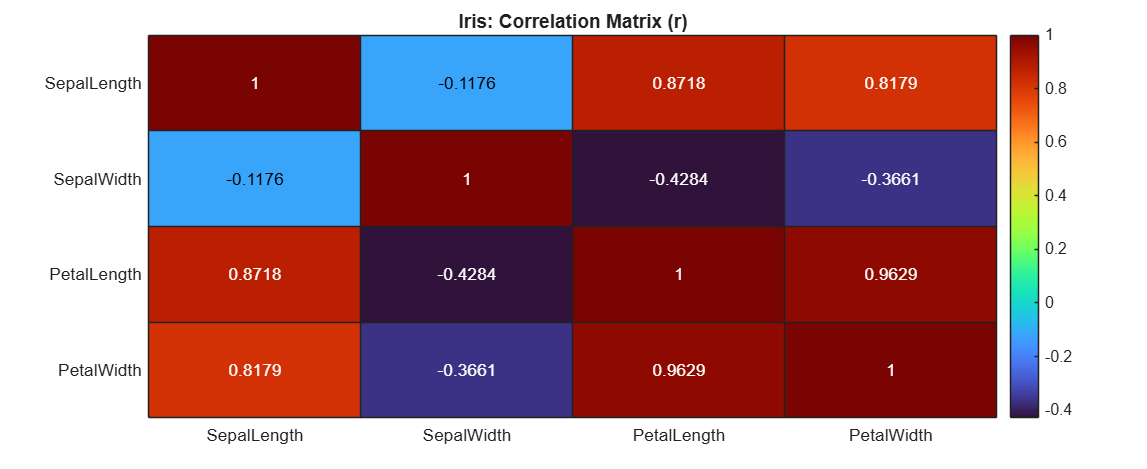


%% ---------- PLOTS ----------
%% ---------- PLOTS ----------
figure('Position',[100 100 1100 450],'Color','w');

heatmap(irisTbl.Properties.VariableNames, ...
        irisTbl.Properties.VariableNames, ...
        C_iris);
colormap(turbo);
title('Iris: Correlation Matrix (r)');

## Practice Exercise

Can you replicate the above code on the patient's dataset?

%% ---------- 2) PATIENTS ----------
disp('===== PATIENT DATASET =====')

===== PATIENT DATASET =====


load patients
patientsTbl = table(Age, Height, Weight, Systolic, Diastolic, ...
    'VariableNames', {'Age','Height','Weight','Systolic','Diastolic'});

% Descriptive Statistics
%Add your code here

% Correlation (patients contains some NaNs so pairwise is important)
%Add your code here

%% ---------- PLOTS ----------
%Add your code here

**MATLAB helper functions **

They are user-defined functions typically created to perform a specific, often repetitive, task that supports a primary script or function. They're essentially sub-routines that break down complex code into smaller, more manageable, and reusable pieces. Helper functions generally:

- **Improve readability** by separating detailed steps from the main logic.

- **Prevent redundancy** by allowing the same code block to be called multiple times.

- **Are often defined at the end of the file** that calls them (as *local functions*), meaning they're only accessible within that single file.

Think of them as assistants: the main script handles the overall project, and the helper functions take care of the frequent, smaller jobs.

%% ================= HELPER FUNCTIONS =================
function statsTable = describeTable(tbl)
% Create a pandas.DataFrame.describe()-style summary for numeric columns
    X = table2array(tbl);
    vn = tbl.Properties.VariableNames;

    count = sum(~isnan(X),1);
    mu    = mean(X, 'omitnan');
    sd    = std(X,  'omitnan');
    mn    = min(X,  [], 'omitnan');
    q25   = quantile(X, 0.25);
    med   = median(X, 'omitnan');
    q75   = quantile(X, 0.75);
    mx    = max(X,  [], 'omitnan');

    statsTable = array2table([count; mu; sd; mn; q25; med; q75; mx], ...
        'RowNames', {'count','mean','std','min','25%','50%','75%','max'}, ...
        'VariableNames', vn);
end

# Challenge Exercise

Combine all three sub-parts by:

- Training a model 30 times (Sub-part 1: central tendency)

- Analyzing prediction confidence variability (Sub-part 2: variability)

- Examining feature correlations before training (Sub-part 3: correlation)

This integrated analysis provides complete understanding of your data and model behavior!